% Task 2b: Brief Analysis of the Given Systems

% Clear the workspace and command window
clear; clc;

%% System 1: G1(s) = 10 / (s^3 + 5.8*s^2 + 8*s + 20)
% Define the transfer function G1(s)
num1 = 10;   % Numerator
den1 = [1 5.8 8 20]; % Denominator coefficients
G1 = tf(num1, den1);

% Analyze System 1
fprintf('System 1: G1(s)\n');

System 1: G1(s)


% Poles
poles_G1 = pole(G1);
zeroes_G1 = zero(G1)


zeroes_G1 =

  0×1 empty double column vector



fprintf('Poles of G1: \n');

Poles of G1: 


disp(poles_G1);

  -5.0000 + 0.0000i
  -0.4000 + 1.9596i
  -0.4000 - 1.9596i



disp(zeroes_G1);

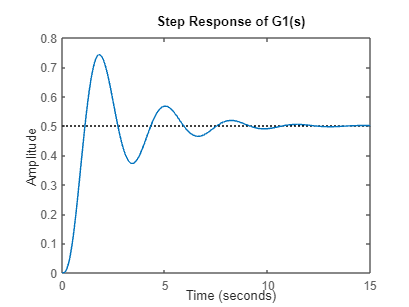


% Step Response
figure;
step(G1);
title('Step Response of G1(s)');

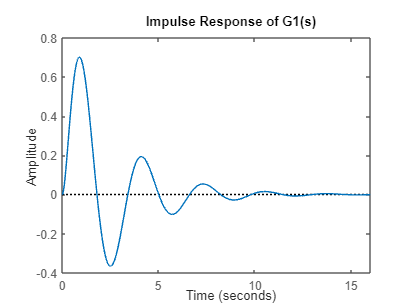

% Impulse Response
figure;
impulse(G1);
title('Impulse Response of G1(s)');

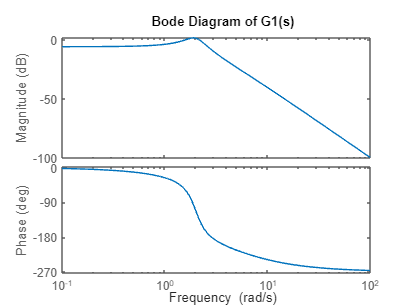

% Bode Diagram
figure;
bode(G1);
title('Bode Diagram of G1(s)');

%% Discretization using Tustin's method
Ts = 0.1;  % Sampling time (you can change this based on your requirement)

% Discrete transfer function using Tustin (bilinear) transformation
G1_discrete = c2d(G1, Ts, 'tustin');

fprintf('Discrete-time transfer function using Tustin method:\n');

Discrete-time transfer function using Tustin method:


G1_discrete

G1_discrete =
 
  0.0009524 z^3 + 0.002857 z^2 + 0.002857 z + 0.0009524
  -----------------------------------------------------
           z^3 - 2.486 z^2 + 2.055 z - 0.5543
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


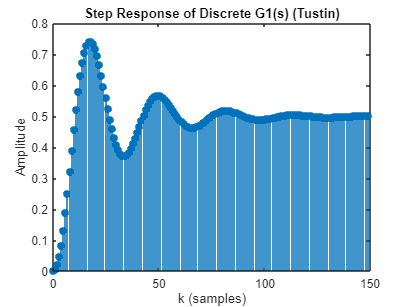

[y_step, t_step] = step(G1_discrete);  % Get the step response and corresponding time vector

figure;
k = 0:length(t_step)-1;  % Generate sample indices (k)
stem(k, y_step, 'filled');  % Use stem plot to show discrete points
xlabel('k (samples)');
ylabel('Amplitude');
title('Step Response of Discrete G1(s) (Tustin)');

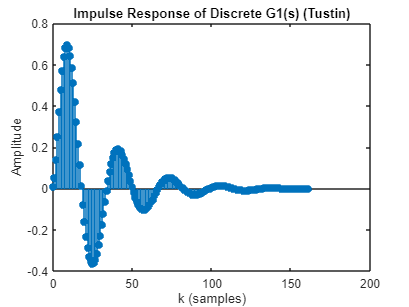

[y_imp, t_step] = impulse(G1_discrete);  % Get the step response and corresponding time vector

figure;
k = 0:length(t_step)-1;  % Generate sample indices (k)
stem(k, y_imp, 'filled');  % Use stem plot to show discrete points
xlabel('k (samples)');
ylabel('Amplitude');
title('Impulse Response of Discrete G1(s) (Tustin)');

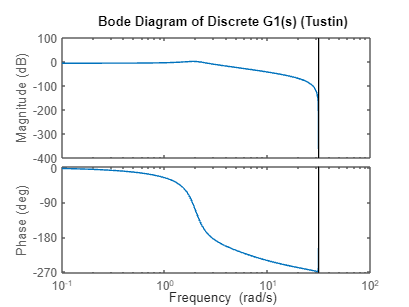


% Bode Diagram of Discrete System
figure;
bode(G1_discrete);
title('Bode Diagram of Discrete G1(s) (Tustin)');

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

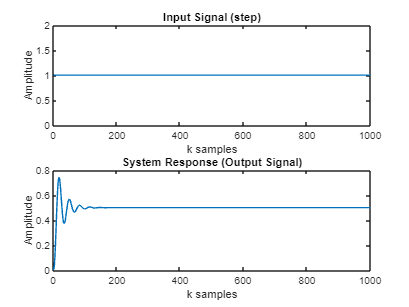

% Set parameters for dataset generation
signal_type = 'step';  % Choose 'step', 'impulse', or 'prbs'
Ts = 0.1;  % Sampling time (e.g., 0.01 for 100 Hz)
N = 1000;  % Number of samples
[u, y_1, t] = generate_dataset(G1_discrete, signal_type, Ts, N);

noise_level = 0.0001;  % Adjust the noise level as desired
y = y_1 + noise_level * randn(size(y_1))

y =     0.0009
    0.0061
    0.0199
    0.0454
    0.0823
    0.1306
    0.1877
    0.2519
    0.3199
    0.3897


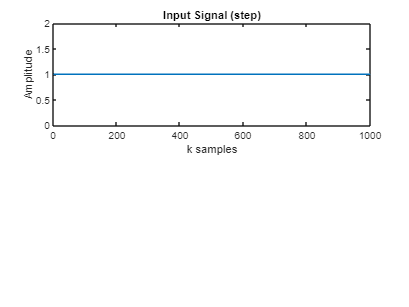

figure;
subplot(2, 1, 1);
plot(u);
title(['Input Signal (', signal_type, ')']);
xlabel('k samples');
ylabel('Amplitude');


[numd, dend] = tfdata(G1, 'v');

% na (order of denominator - number of past outputs)
na = length(dend) - 1;

% nb (order of numerator - number of past inputs)
nb = length(numd) - 1;

% nk (input-output delay)
nk = find(numd ~= 0, 1) - 1;  % Delay in time steps

% Display na, nb, and nk
fprintf('Extracted ARX Model Parameters:\n');

Extracted ARX Model Parameters:


fprintf('na (order of past outputs) = %d\n', na);

na (order of past outputs) = 3


fprintf('nb (order of past inputs) = %d\n', nb);

nb (order of past inputs) = 3


fprintf('nk (input-output delay) = %d\n', nk);

nk (input-output delay) = 3


% Create regression matrix
[X] = create_regression_matrix(u, y, na, nb, nk);
disp('Regression Matrix (X):');

Regression Matrix (X):


disp(X);

    1.0000    1.0000    1.0000   -0.0199   -0.0061   -0.0009
    1.0000    1.0000    1.0000   -0.0454   -0.0199   -0.0061
    1.0000    1.0000    1.0000   -0.0823   -0.0454   -0.0199
    1.0000    1.0000    1.0000   -0.1306   -0.0823   -0.0454
    1.0000    1.0000    1.0000   -0.1877   -0.1306   -0.0823
    1.0000    1.0000    1.0000   -0.2519   -0.1877   -0.1306
    1.0000    1.0000    1.0000   -0.3199   -0.2519   -0.1877
    1.0000    1.0000    1.0000   -0.3897   -0.3199   -0.2519
    1.0000    1.0000    1.0000   -0.4578   -0.3897   -0.3199
    1.0000    1.0000    1.0000   -0.5225   -0.4578   -0.3897
    1.0000    1.0000    1.0000   -0.5811   -0.5225   -0.4578
    1.0000    1.0000    1.0000   -0.6324   -0.5811   -0.5225
    1.0000    1.0000    1.0000   -0.6747   -0.6324   -0.5811
    1.0000    1.0000    1.0000   -0.7066   -0.6747   -0.6324
    1.0000    1.0000    1.0000   -0.7288   -0.7066   -0.6747
    1.0000    1.0000    1.0000   -0.7404   -0.7288   -0.7066
    1.0000    1.0000    

% Least Square
y_ls = create_output_vector(y, na);

% parameters using LS
[theta] = least_squares_theta(X, y_ls);
disp('Least squares estimate of theta:');

Least squares estimate of theta:


disp(theta);

    0.0094
    0.0094
    0.0094
   -1.2286
   -0.3057
    0.5910




% Simulate model output
y_sim = simulate_model_ARX(theta, u, na, nb, nk);
disp(y_sim);

         0
    0.0094
    0.0305
    0.0687
    0.1164
    0.1744
    0.2376
    0.3047
    0.3723
    0.4385
    0.5007
    0.5576
    0.6073
    0.6490
    0.6818
    0.7055
    0.7200
    0.7257
    0.7231
    0.7130
    0.6965
    0.6747
    0.6488
    0.6201
    0.5897
    0.5590
    0.5290
    0.5006
    0.4747
    0.4520
    0.4329
    0.4178
    0.4068
    0.4001
    0.3973
    0.3983
    0.4028
    0.4101
    0.4199
    0.4316
    0.4446
    0.4583
    0.4723
    0.4859
    0.4988
    0.5106
    0.5210
    0.5298
    0.5367
    0.5418
    0.5449
    0.5462
    0.5459
    0.5439
    0.5406
    0.5362
    0.5310
    0.5251
    0.5189
    0.5126
    0.5063
    0.5005
    0.4951
    0.4903
    0.4863
    0.4832
    0.4808
    0.4793
    0.4787
    0.4789
    0.4797
    0.4812
    0.4831
    0.4855
    0.4882
    0.4910
    0.4938
    0.4967
    0.4993
    0.5018
    0.5040
    0.5058
    0.5073
    0.5083
    0.5090
    0.5093
    0.5093
    0.5089
    0.5083
    0.5074
    0.5063

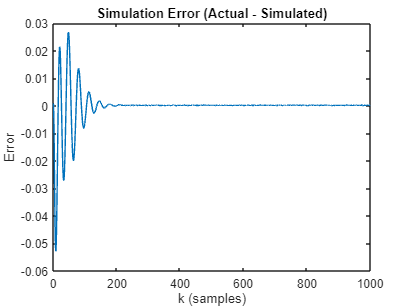

figure;
plot(y-y_sim);
xlabel('k (samples)');
ylabel('Error');
title('Simulation Error (Actual - Simulated)');

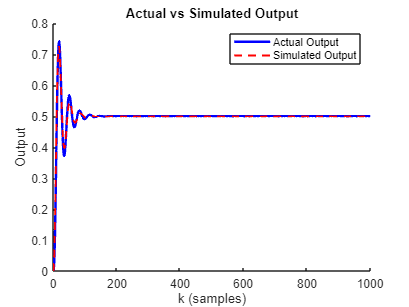

figure;
hold on;
plot(y, 'b', 'LineWidth', 2);  % Actual output in blue, thicker line
plot(y_sim, 'r--', 'LineWidth', 1.5);  % Simulated output in red dashed line
hold off;
xlabel('k (samples)');
ylabel('Output');
legend('Actual Output', 'Simulated Output');
title('Actual vs Simulated Output');

[uf,yf] = simulate_1F_model(theta, u, y, nb, nk)

uf =     1.0000
    0.1861
   -3.0849
   -1.3929
   -1.3929
   -1.3929
   -1.3929
   -1.3929
   -1.3929
   -1.3929


yf =     0.0009
    0.0054
    0.0121
    0.0107
   -0.0095
   -0.0511
   -0.1111
   -0.1887
   -0.2781
   -0.3769


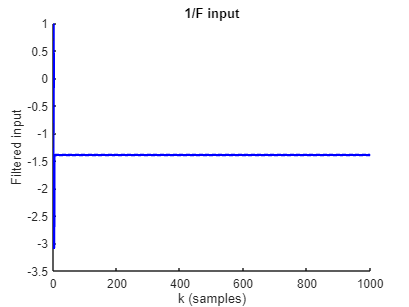

figure;
hold on;
plot(uf,'b', 'LineWidth', 2);
xlabel('k (samples)');
ylabel('Filtered input');
title('1/F input');

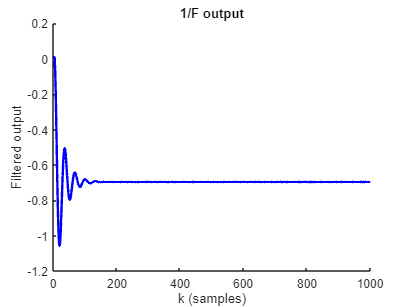

figure;
hold on;
plot(yf,'b', 'LineWidth', 2);
xlabel('k (samples)');
ylabel('Filtered output');
title('1/F output');

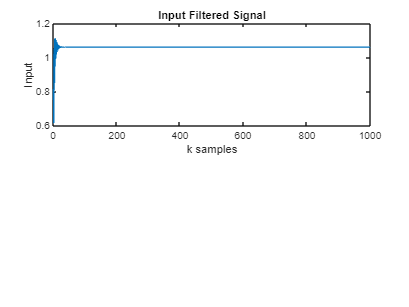

fil = theta(na+1:end);
u_fil = filter(1, -fil, u);
y_fil = filter(1, -fil, y);

figure;
subplot(2,1,1);
plot(u_fil);
title('Input Filtered Signal');
xlabel('k samples');
ylabel('Input');

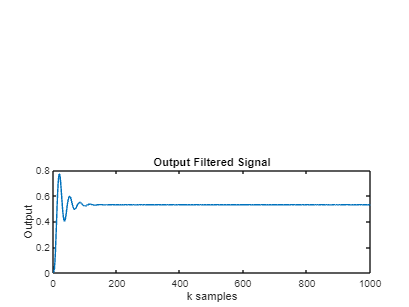


figure;
subplot(2,1,2);
plot(y_fil);
title('Output Filtered Signal');
xlabel('k samples');
ylabel('Output');

[Z] = create_IVregression_matrix(u, y_sim, na, nb, nk);
disp('Regression Matrix (Z):');

Regression Matrix (Z):


disp(Z);

    1.0000    1.0000    1.0000   -0.0305   -0.0094         0
    1.0000    1.0000    1.0000   -0.0687   -0.0305   -0.0094
    1.0000    1.0000    1.0000   -0.1164   -0.0687   -0.0305
    1.0000    1.0000    1.0000   -0.1744   -0.1164   -0.0687
    1.0000    1.0000    1.0000   -0.2376   -0.1744   -0.1164
    1.0000    1.0000    1.0000   -0.3047   -0.2376   -0.1744
    1.0000    1.0000    1.0000   -0.3723   -0.3047   -0.2376
    1.0000    1.0000    1.0000   -0.4385   -0.3723   -0.3047
    1.0000    1.0000    1.0000   -0.5007   -0.4385   -0.3723
    1.0000    1.0000    1.0000   -0.5576   -0.5007   -0.4385
    1.0000    1.0000    1.0000   -0.6073   -0.5576   -0.5007
    1.0000    1.0000    1.0000   -0.6490   -0.6073   -0.5576
    1.0000    1.0000    1.0000   -0.6818   -0.6490   -0.6073
    1.0000    1.0000    1.0000   -0.7055   -0.6818   -0.6490
    1.0000    1.0000    1.0000   -0.7200   -0.7055   -0.6818
    1.0000    1.0000    1.0000   -0.7257   -0.7200   -0.7055
    1.0000    1.0000    

% IV
y_iv = create_output_vector(y_sim, na);


% parameters using LS
[theta_iv] = least_squares_theta(Z, y_iv);
disp('Instrumental Variables estimate of theta:');

Instrumental Variables estimate of theta:


disp(theta_iv);

    0.0099
    0.0099
    0.0099
   -1.1948
   -0.3442
    0.5986



y_sim1 = simulate_model_ARX(theta_iv, u, na, nb, nk);
disp(y_sim1);

         0
    0.0099
    0.0317
    0.0710
    0.1196
    0.1782
    0.2413
    0.3078
    0.3739
    0.4380
    0.4976
    0.5513
    0.5976
    0.6357
    0.6650
    0.6854
    0.6971
    0.7006
    0.6965
    0.6859
    0.6697
    0.6491
    0.6252
    0.5994
    0.5726
    0.5460
    0.5205
    0.4969
    0.4757
    0.4577
    0.4429
    0.4318
    0.4242
    0.4201
    0.4192
    0.4214
    0.4261
    0.4329
    0.4415
    0.4513
    0.4618
    0.4726
    0.4832
    0.4934
    0.5028
    0.5111
    0.5181
    0.5238
    0.5280
    0.5308
    0.5323
    0.5324
    0.5313
    0.5293
    0.5264
    0.5228
    0.5188
    0.5145
    0.5102
    0.5059
    0.5019
    0.4982
    0.4949
    0.4922
    0.4900
    0.4884
    0.4874
    0.4869
    0.4869
    0.4874
    0.4883
    0.4895
    0.4910
    0.4926
    0.4944
    0.4961
    0.4978
    0.4994
    0.5009
    0.5022
    0.5032
    0.5041
    0.5047
    0.5051
    0.5052
    0.5052
    0.5049
    0.5045
    0.5040
    0.5034
    0.5028

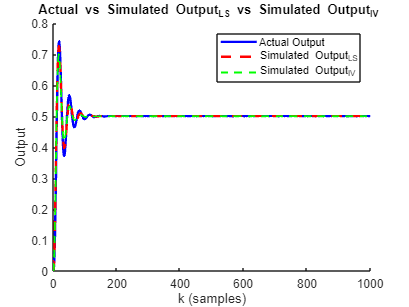

y_simff = simulate_model_ARX(theta_iv, u_fil, na, nb, nk);
figure;
hold on;
plot(y, 'b', 'LineWidth', 2);  % Actual output in blue, thicker line
plot(y_sim, 'r--', 'LineWidth', 2);  % Simulated output in red dashed line
plot(y_sim1, 'g--', 'LineWidth', 1.5);
hold off;
xlabel('k (samples)');
ylabel('Output');
legend('Actual Output', 'Simulated Output_LS', 'Simulated Output_IV');
title('Actual vs Simulated Output_LS vs Simulated Output_IV ');

y_f = y(201:N);
[X_fir, theta_fir] = calculate_FIR_output(u, y_f, 200);
disp(X_fir);

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

disp(theta_fir);

    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025

[y_fir] = simulate_model_FIR(theta_fir, u, 200);
disp(y_fir);

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0

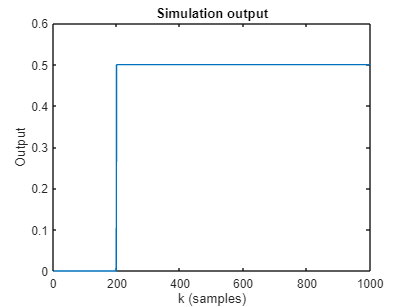

figure;
plot(y_fir);
xlabel('k (samples)');
ylabel('Output');
title('Simulation output');

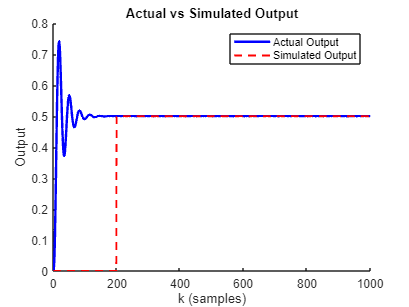

figure;
hold on;
plot(y, 'b', 'LineWidth', 2);  % Actual output in blue, thicker line
plot(y_fir, 'r--', 'LineWidth', 1.5);  % Simulated output in red dashed line
hold off;
xlabel('k (samples)');
ylabel('Output');
legend('Actual Output', 'Simulated Output');
title('Actual vs Simulated Output');

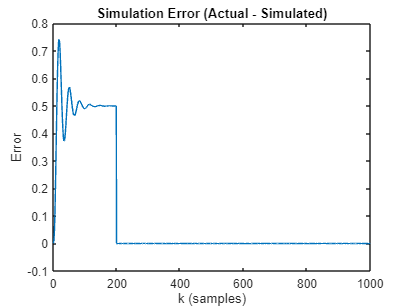

figure;
plot(y-y_fir);
xlabel('k (samples)');
ylabel('Error');
title('Simulation Error (Actual - Simulated)');


cf = cost(theta, uf, yf, nb, na, nk);


theta_opt = optimize_OE_model(uf, yf, na, nb, nk, theta);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           7         0.207514                          20.9
     1          70         0.207453    1.90984e-07             14  
     2          98         0.182348        810.467           18.9  
     3         105         0.180562              1           19.6  
     4         126         0.169361             91           86.8  
     5         133         0.137005              1            167  
     6         140        0.0808981              1            197  
     7         147        0.0600868              1            104  
     8         154        0.0563797              1           19.2  
     9         161        0.0562306              1           0.87  
    10         168        0.0562304              1           0.79  
    11         175        0.0562302              1          0.769  
    12         182        0.0562288              

disp(theta_opt);

    0.0003
    0.0038
    0.0261
   -1.2322
   -0.3044
    0.5969



y_simf = simulate_model_ARX(theta_opt, uf, na, nb, nk);
y_simf1 = simulate_model_ARX(theta_opt, u_fil, na, nb, nk);

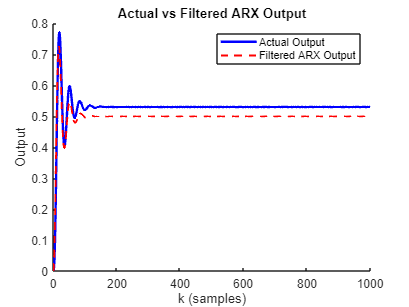

figure;
hold on;
plot(y_fil, 'b', 'LineWidth', 2);  % Actual output in blue, thicker line
plot(y_sim, 'r--', 'LineWidth', 1.5);  % Simulated output in red dashed line
hold off;
xlabel('k (samples)');
ylabel('Output');
legend('Actual Output', 'Filtered ARX Output');
title('Actual vs Filtered ARX Output');

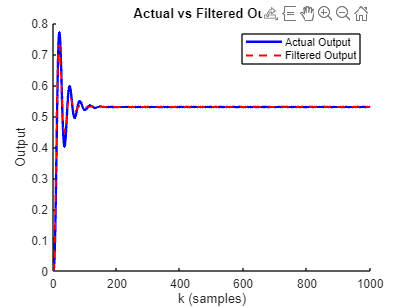

figure;
hold on;
plot(y_fil, 'b', 'LineWidth', 2);  % Actual output in blue, thicker line
plot(y_simff, 'r--', 'LineWidth', 1.5);  % Simulated output in red dashed line
hold off;
xlabel('k (samples)');
ylabel('Output');
legend('Actual Output', 'Filtered Output');
title('Actual vs Filtered Output');

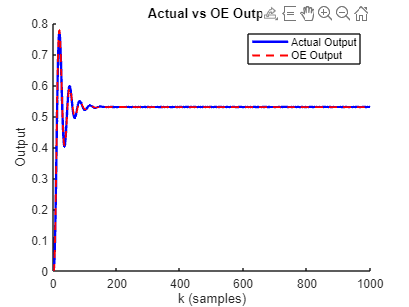

figure;
hold on;
plot(y_fil, 'b', 'LineWidth', 2);  % Actual output in blue, thicker line
plot(y_simf1, 'r--', 'LineWidth', 1.5);  % Simulated output in red dashed line
hold off;
xlabel('k (samples)');
ylabel('Output');
legend('Actual Output', 'OE Output');
title('Actual vs OE Output');

rmse_fil = sum_squared_error( y , y_fil);
disp('RMS value of iv');

RMS value of iv


disp(rmse_fil);

    0.0304



rmse_arx = sum_squared_error( y , y_sim);
disp('RMS value of ARX');

RMS value of ARX


disp(rmse_arx);

    0.0061



rmse_iv = sum_squared_error( y , y_sim1);
disp('RMS value of iv');

RMS value of iv


disp(rmse_iv);

    0.0083



rmse_fir = sum_squared_error( y , y_fir);
disp('RMS value of FIR');

RMS value of FIR


disp(rmse_fir);

    0.2233



rmse_oe = sum_squared_error( yf , y_simf);
disp('RMS value of OE');

RMS value of OE


disp(rmse_oe);

    0.0037



rmse_oe1 = sum_squared_error( y_fil , y_simf1);
disp('RMS value of OE');

RMS value of OE


disp(rmse_oe1);

    0.0023

